% Define system parameters
g = 9.81;           % acceleration due to gravity
mass_quad = 1.5;    % mass of the quadrotor in kilograms
M_x_quad = 0.0190;  % moment of inertia about x axis in kg*m^2
M_y_quad = 0.0190;  % moment of inertia about y axis in kg*m^2
M_z_quad = 0.0252;  % moment of inertia about z axis in kg*m^2
n_c = 2.021382751247327e-04; % linear relationship between PWM and thrust
n_t = 1.500108339272986;     % linear relationship between PWM and torque
L = 0.25;           % Length of quad arm in metres
theta = 45;

## state order [x; y; z; x'; y' ;z' ; phi ;theta ; psi ; phi' ; theta' ; psi'];

quad_state_A = [0 0 0 1 0 0 0 0 0 0 0 0 ;
                0 0 0 0 1 0 0 0 0 0 0 0 ; 
                0 0 0 0 0 1 0 0 0 0 0 0 ;
                0 0 0 0 0 0 0 -g 0 0 0 0 ;
                0 0 0 0 0 0 g 0 0 0 0 0 ;
                0 0 0 0 0 0 0 0 0 0 0 0 ;
                0 0 0 0 0 0 0 0 0 1 0 0 ;
                0 0 0 0 0 0 0 0 0 0 1 0 ;
                0 0 0 0 0 0 0 0 0 0 0 1 ;
                0 0 0 0 0 0 0 0 0 0 0 0 ;
                0 0 0 0 0 0 0 0 0 0 0 0 ;
                0 0 0 0 0 0 0 0 0 0 0 0 ];

quad_actuator_B = [ 0 0 0 0 ;
                    0 0 0 0 ;
                    0 0 0 0 ;
                    0 0 0 0 ;
                    0 0 0 0 ;
                    1/mass_quad 0 0 0 ;
                    0 0 0 0 ;
                    0 0 0 0 ;
                    0 0 0 0 ;
                    0 1/M_x_quad 0 0 ;
                    0 0 1/M_y_quad 0 ; 
                    0 0 0 1/M_z_quad ; ];
observer_C = [1 0 0 0 0 0 0 0 0 0 0 0 ;
              0 1 0 0 0 0 0 0 0 0 0 0 ;
              0 0 1 0 0 0 0 0 0 0 0 0 ;
              0 0 0 1 0 0 0 0 0 0 0 0 ;
              0 0 0 0 1 0 0 0 0 0 0 0 ;
              0 0 0 0 0 1 0 0 0 0 0 0 ;
              0 0 0 0 0 0 1 0 0 0 0 0 ;
              0 0 0 0 0 0 0 1 0 0 0 0 ;
              0 0 0 0 0 0 0 0 1 0 0 0 ;
              0 0 0 0 0 0 0 0 0 1 0 0 ;
              0 0 0 0 0 0 0 0 0 0 1 0 ;
              0 0 0 0 0 0 0 0 0 0 0 1 ];

D=zeros(12,4);

## cost functions for lqr

Q =          [1000 0 0 0 0 0 0 0 0 0 0 0 ;
              0 1000 0 0 0 0 0 0 0 0 0 0 ;
              0 0 1000 0 0 0 0 0 0 0 0 0 ;
              0 0 0 0.001 0 0 0 0 0 0 0 0 ;
              0 0 0 0 0.001 0 0 0 0 0 0 0 ;
              0 0 0 0 0 0.001 0 0 0 0 0 0 ;
              0 0 0 0 0 0 100 0 0 0 0 0 ;
              0 0 0 0 0 0 0 1000 0 0 0 0 ;
              0 0 0 0 0 0 0 0 10 0 0 0 ;
              0 0 0 0 0 0 0 0 0 10 0 0 ;
              0 0 0 0 0 0 0 0 0 0 10 0 ;
              0 0 0 0 0 0 0 0 0 0 0 10 ];

R = eye(4);

sys = ss(quad_state_A,quad_actuator_B,observer_C,D);


lqr1 = lqr(sys,Q,R)

lqr1 =    -0.0000   -0.0000   31.6228   -0.0000   -0.0000    9.7401   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000   31.6228   -0.0000   -0.0000   14.4009   -0.0000   32.1672    0.0000    0.0000    3.3500    0.0000   -0.0000
  -31.6228    0.0000    0.0000  -14.4009    0.0000   -0.0000    0.0000   32.1672   -0.0000   -0.0000    3.3500   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    3.1623   -0.0000    0.0000    3.1874



lqr_sys = feedback(sys,lqr1,-1)

lqr_sys =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1            0           0           0           1           0           0           0           0           0           0           0           0
   x2            0           0           0           0           1           0           0           0           0           0           0           0
   x3            0           0           0           0           0           1           0           0           0           0           0           0
   x4            0           0           0           0           0           0           0       -9.81           0           0           0           0
   x5            0           0           0           0           0           0        9.81           0           0           0           0           0
   x6    1.023e-13   1.232e-13      -21.08   2.534e-14    5.16e-14      -6.

lqr_sys_controllability = rank(ctrb(quad_state_A,quad_actuator_B))

lqr_sys_controllability = 12

lqr_sys_observability   = rank(obsv(quad_state_A,observer_C))

lqr_sys_observability = 12

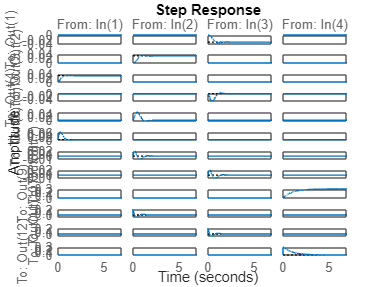

figure
step(lqr_sys)